## EDGE FILTERING

**(Robert, Prewitt, Sobel) **

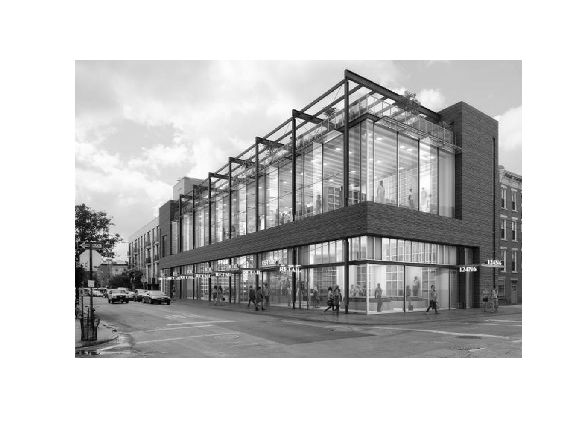

clf;
I = rgb2gray(imread('BUILDING.jpg'));
imshow(I);

# **Robert **

Finds edges at those points where the gradient of `I` is maximum, using the Roberts approximation to the derivative.

**-1 0       0 -1**

**0 1        1 0**

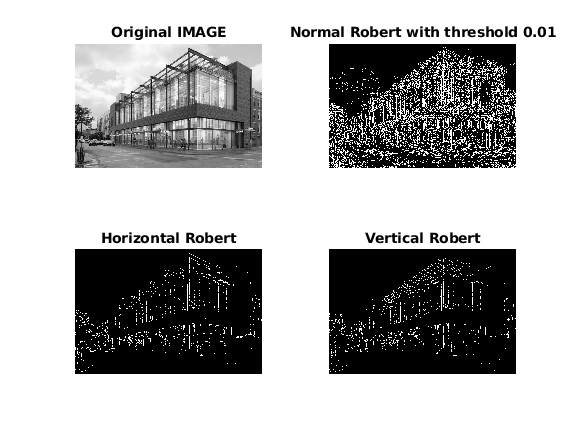

%Pre Defined Method
clf;
R0= edge(I,'Roberts',0.01);
R1 = edge(I,'Roberts','horizontal');
R2= edge(I,'Roberts','vertical');
subplot(221);imshow(I);title('Original IMAGE');
subplot(222);imshow(R0);title('Normal Robert with threshold 0.01');
subplot(223);imshow(R1);title('Horizontal Robert');
subplot(224);imshow(R2);title('Vertical Robert');

# **Prewitt**

Finds edges at those points where the gradient of `I` is maximum, using the Prewitt approximation to the derivative.

**-1    -1    -1               -1    0    1**

**0    0    0                    -1    0    1**

**1    1    1                    -1    0    1**

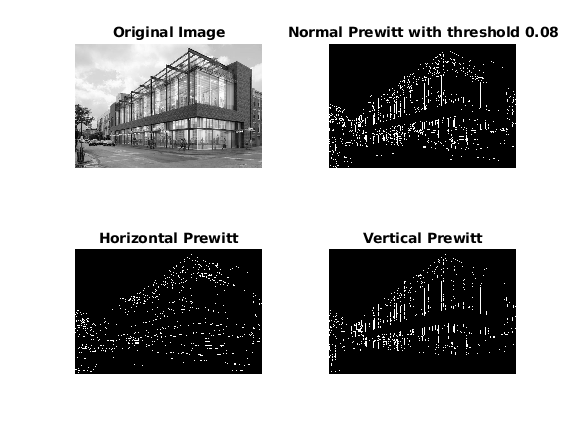

%Predefined Method
clf;
P0= edge(I,'Prewitt',0.08);
P1 = edge(I,'Prewitt','horizontal');
P2= edge(I,'Prewitt','vertical');
subplot(221);imshow(I);title('Original Image');
subplot(222);imshow(P0);title('Normal Prewitt with threshold 0.08');
subplot(223);imshow(P1);title('Horizontal Prewitt');
subplot(224);imshow(P2);title('Vertical Prewitt');

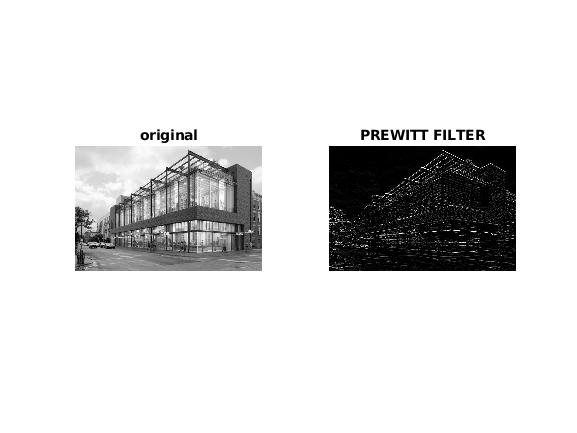

% ANOTHER METHOD
clf;
P3 = fspecial('prewitt');
P4 = imfilter(I,P3,'replicate');
subplot(121);imshow(I);title('original');
subplot(122);imshow(P4);title('PREWITT FILTER');

# **Sobel** 

Finds edges at those points where the gradient of the image `I` is maximum, using the Sobel approximation to the derivative.

**-1    -2    -1               -1    0    1**

**0    0    0                    -2    0    2**

**1    2    1                    -1    0    1**

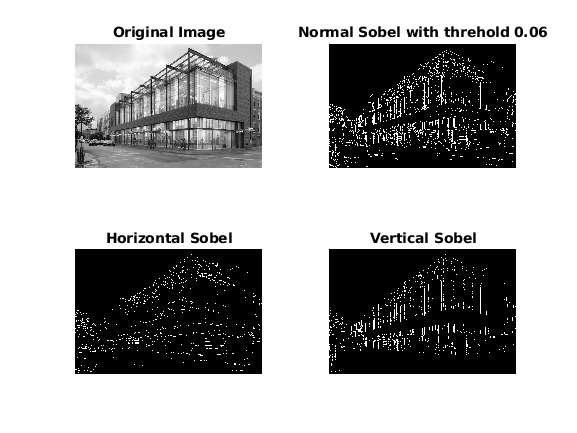

%Predefined Method
clf;
S0= edge(I,'Sobel',0.06);
S1 = edge(I,'Sobel','horizontal');
S2= edge(I,'Sobel','vertical');
subplot(221);imshow(I);title('Original Image');
subplot(222);imshow(S0);title('Normal Sobel with threhold 0.06');
subplot(223);imshow(S1);title('Horizontal Sobel');
subplot(224);imshow(S2);title('Vertical Sobel');

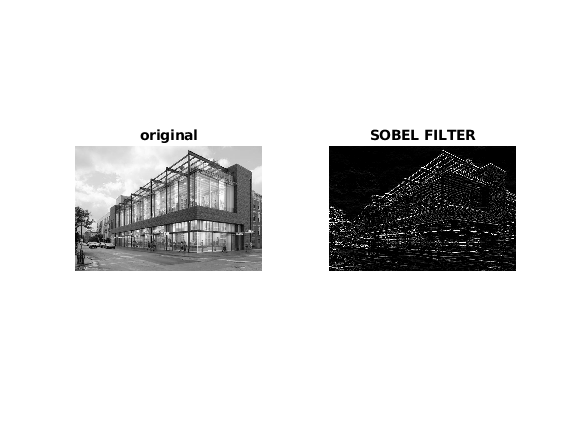

% ANOTHER METHOD
clf;
P3 = fspecial('sobel');
P4 = imfilter(I,P3,'replicate');
subplot(121);imshow(I);title('original');
subplot(122);imshow(P4);title('SOBEL FILTER');

# CANNY

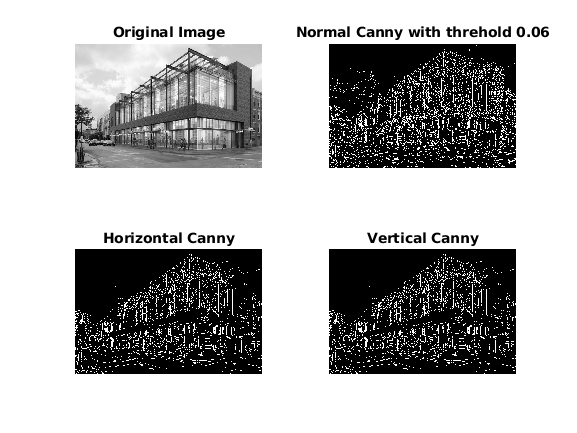

% Pre-defined funtion
clf;
C0= edge(I,'Canny',0.05);
C1 = edge(I,'Canny','horizontal');
C2= edge(I,'Canny','vertical');
subplot(221);imshow(I);title('Original Image');
subplot(222);imshow(C0);title('Normal Canny with threhold 0.06');
subplot(223);imshow(C1);title('Horizontal Canny');
subplot(224);imshow(C2);title('Vertical Canny');

# LOG

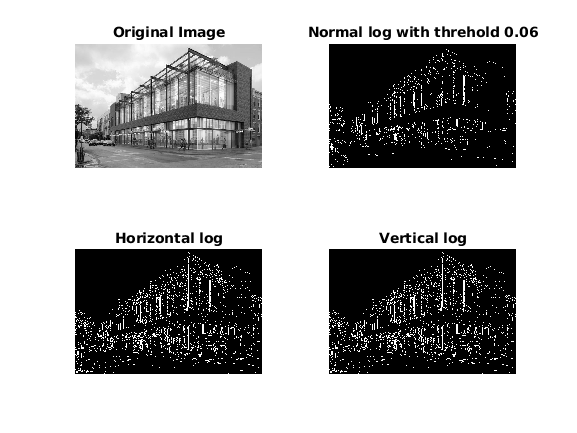

% Pre-defined funtion
clf;
C0= edge(I,'log',0.01);
C1 = edge(I,'log','horizontal');
C2= edge(I,'log','vertical');
subplot(221);imshow(I);title('Original Image');
subplot(222);imshow(C0);title('Normal log with threhold 0.06');
subplot(223);imshow(C1);title('Horizontal log');
subplot(224);imshow(C2);title('Vertical log');

# Edge detection with different Kernel Sizes

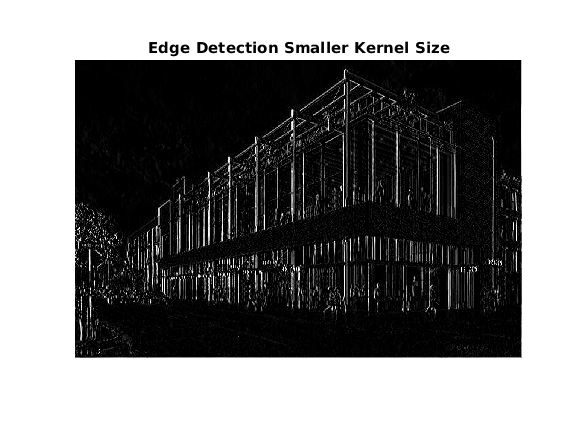

%Small Kernel Size in y-direction
clf;
small_mask=[1, 0, -1;1, 0, -1;1, 0, -1]; 
In=I;
for i=2:size(I, 1)-1
 for j=2:size(I, 2)-1
 
 %multiplying mask value with the corresponding image pixel value 
 neighbour_matrix=small_mask.* double(In(i-1:i+1, j-1:j+1)); 
 avg_value=sum(neighbour_matrix(:)); 
 ln(i, j)=avg_value; 
 end 
end 
imshow(ln);
title("Edge Detection Smaller Kernel Size");

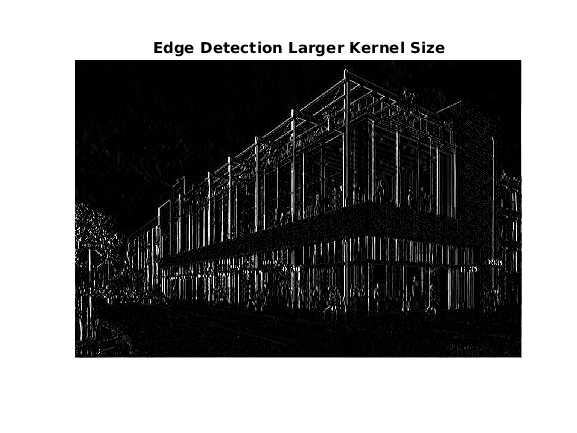

% Larger kernel size in filter with diagonal mask
clf;
large_mask=[1, 1, 1,1,1;0, 1,0,1,0;-1, 0, -1,0,-1;1,-1,1,-1,1;0,-1,1,0,-1]; 
In=I;

for i=2:size(I, 3)-2
 for j=2:size(I, 4)-2
     
 % Multiplying mask value with the corresponding image pixel value 
 neighbour_matrix=large_mask.* double(In(i-1:i+1, j-1:j+1)); 
 avg_value=sum(neighbour_matrix(:)); 
 ln(i, j)=avg_value; 
 end 
end 
imshow(ln);
title("Edge Detection Larger Kernel Size");